Directly QF on x axis.

clear all;
close all;
clc;

load JND_first.mat;
load JND_second.mat;
load JND_third.mat;
data_QF = JND_result_first(10, :);
[N,edges] = histcounts(data_QF);
bin_center = edges + 0.5;
bin_center(end) = [];
n = length(data_QF);
prob = N / n ;
bar(bin_center,prob,'hist');
hold on;
h_gca = gca;
h = h_gca.Children;
h.FaceColor = [0.9 0.9 0.9];
xlabel('Distortion level');
ylabel('Probability Density');
xlim([0 100]);
pd_GEV = fitdist(data_QF','GeneralizedExtremeValue');
pdf_GEV = pdf(pd_GEV,0:100);
plot(0:100,pdf_GEV,'g');
% SUR there (for GEV)
cdf_GEV = cdf(pd_GEV, 0:100);
% SUR curve.
SUR = 1 - cdf_GEV;
plot(0:100,SUR)
ecdf(data_QF,'function','survivor')
legend("Histogram", "PDF", "SUR", "Empirical SUR",'AutoUpdate', 'off', 'Location','east');
inverse_distortion_result = icdf(pd_GEV, 0.25);

point = [inverse_distortion_result, 0.75];   % Here the point that will have the reference lines
plot(point(1), point(2), 'o')
plot([point(1), point(1)], [0, point(2)], 'k--')  %vertical line
plot([0, point(1)], [point(2), point(2)], 'k--')  %horizontal line
xlabel('QF');
ylabel('');
hold off;




Directly distortion level on x axis.

clear all;
close all;
clc;

load JND_first.mat;
load JND_second.mat;
load JND_third.mat;
 data_QF = JND_result_first(10, :);
    data_distortion_level = 101 - data_QF;
    % histogram(data_distortion_level);
    % hold on;
    % ylim([0 10]);
    % xlim([0 100]);
    % h_gca = gca;
    % h = h_gca.Children;
    % h.FaceColor = [.9 .9 .9];
    % h.EdgeColor = [.9 .9 .9];
    [N,edges] = histcounts(data_distortion_level);
    bin_center = edges + 0.5;
    bin_center(end) = [];
    % plot(bin_center,N,'o');
    % hold off;
    n = length(data_distortion_level);
    prob = N / n ;
    bar(bin_center,prob,'hist');
    hold on;
    h_gca = gca;
    h = h_gca.Children;
    h.FaceColor = [0.9 0.9 0.9];
    xlabel('Distortion level');
    ylabel('Probability Density');
    xlim([0 100]);
    pd_GEV_DL = fitdist(data_distortion_level','GeneralizedExtremeValue');
    pdf_GEV_QF = pdf(pd_GEV_DL,0:100);
    plot(0:100,pdf_GEV_QF,'g');
    % SUR there (for GEV)
    cdf_GEV = cdf(pd_GEV_DL, 0:100);
    % SUR curve.
    SUR = 1 - cdf_GEV;
    plot(0:100,SUR)
    ecdf(data_distortion_level,'function','survivor')
    legend("Histogram", "PDF", "SUR", "Empirical SUR",'AutoUpdate', 'off', 'Location','west');
    % title("Data fitting for first JND with image index 3");
    % hold off;
    inverse_distortion_result = icdf(pd_GEV_DL, 0.25);
    
    point = [inverse_distortion_result, 0.75];   % Here the point that will have the reference lines
    plot(point(1), point(2), 'o')
    plot([point(1), point(1)], [0, point(2)], 'k--')  %vertical line
    plot([0, point(1)], [point(2), point(2)], 'k--')  %horizontal line
    xlabel('Distortion Level');
    ylabel('');
    hold off;


By using probability transformation rules, using QF. But distortion level on x-axis.

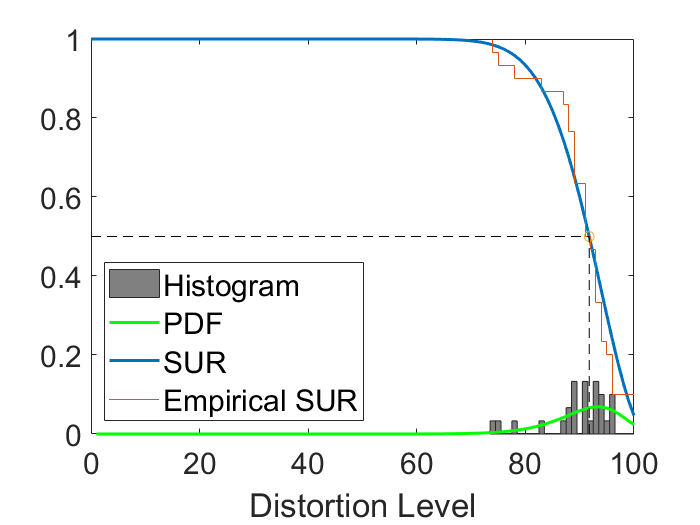

clear all;
close all;
clc;

load JND_first.mat;
load JND_second.mat;
load JND_third.mat;
data_QF = JND_result_third(14, :);
data_distortion_level = 101 - data_QF;
% histogram(data_distortion_level);
% hold on;
% ylim([0 10]);
% xlim([0 100]);
% h_gca = gca;
% h = h_gca.Children;
% h.FaceColor = [.9 .9 .9];
% h.EdgeColor = [.9 .9 .9];
[N,edges] = histcounts(data_distortion_level);
bin_center = edges + 0.5;
bin_center(end) = [];
% plot(bin_center,N,'o');
% hold off;
n = length(data_distortion_level);
prob = N / n ;
bar(bin_center,prob,'hist');
hold on;
h_gca = gca;
h = h_gca.Children;
h.FaceColor = [0.5 0.5 0.5];
xlabel('Distortion level');
ylabel('Probability Density');
xlim([0 100]);
pd_GEV_DL = fitdist(data_distortion_level','GeneralizedExtremeValue');
pd_GEV_QF = fitdist(data_QF','GeneralizedExtremeValue');
pdf_GEV_QF = pdf(pd_GEV_QF,0:100);
pdf_GEV_QF_inverse = pdf_GEV_QF(end:-1:1);
plot(1:101,pdf_GEV_QF_inverse,'g', 'LineWidth', 1.8);
% SUR there (for GEV)
cdf_GEV = cdf(pd_GEV_DL, 0:100);
% SUR curve.
SUR = 1 - cdf_GEV;
plot(0:100,SUR, 'LineWidth', 1.8);
ecdf(data_distortion_level,'function','survivor');
lgd = legend("Histogram", "PDF", "SUR", "Empirical SUR",'AutoUpdate', 'off', 'Location','southwest');
lgd.FontSize = 18;
% title("Data fitting for first JND with image index 3");
% hold off;
inverse_distortion_result = icdf(pd_GEV_DL, 0.5);

point = [inverse_distortion_result, 0.5];   % Here the point that will have the reference lines
plot(point(1), point(2), 'o')
plot([point(1), point(1)], [0, point(2)], 'k--')  %vertical line
plot([0, point(1)], [point(2), point(2)], 'k--')  %horizontal line
xlabel('Distortion Level', 'FontSize', 18);
ylabel('');
set(gca,'FontSize',18)
hold off;